# ThermoeconomicTool demo

Analyze an ORC system, and compare two system configurations:

(1) Produce only electricity working at 30°C condensing temperature (TCND30)

(2) Produce electricity and low-temperature heat for a refrigeration cycle, working at a condensing temperature of 45ºC (TCND45)

**(1) Read data model **

Read the data file and create the model with some parameters

model=ThermoeconomicTool('rorc_model.xlsx',...
    'CostTables','ALL',...
    'DiagnosisMethod','NONE',...
    'debug',false);

INFO: cStatusLogger. Productive Structure is valid
INFO: cStatusLogger. Format Configuration is valid
INFO: cStatusLogger. Exergy values [TCND30] are valid
INFO: cStatusLogger. Exergy values [TCND45] are valid
INFO: cStatusLogger. Exergy values [ETAT75] are valid
INFO: cStatusLogger. Exergy values [PBLR15] are valid
INFO: cStatusLogger. Exergy values [NoIHE] are valid
INFO: cStatusLogger. Exergy values [N_Butane] are valid
INFO: cStatusLogger. Resources Cost sample [Base] is valid
INFO: cStatusLogger. Waste definition is valid
INFO: cReadModelXLS. Data Model rorc_model.xlsx is valid


**(2) Print the results for TCND30**

Print the model results and show the ICT graph

printResults(model);

Flows Table

  Id  Key   From    To      Type     
--------------------------------------
   1  B1    BLR_P1  TRB_F1  INTERNAL 
   2  B2    TRB_F1  IHE_F1  INTERNAL 
   3  B3    IHE_F1  CND_F1  INTERNAL 
   4  B4    CND_F1  PMP_P1  INTERNAL 
   5  B5    PMP_P1  IHE_P1  INTERNAL 
   6  B6    IHE_P1  BLR_P1  INTERNAL 
   7  QBLR  ENV_R1  BLR_F1  RESOURCE 
   8  WP    TRB_P1  PMP_F1  INTERNAL 
   9  WN    TRB_P1  ENV_O1  OUTPUT   
  10  QCND  CND_P1  ENV_W1  WASTE    


Streams Table

  Id  Key     Definition  Type     
------------------------------------
   1  BLR_F1  QBLR        FUEL     
   2  BLR_P1  B1-B6       PRODUCT  
   3  TRB_F1  B1-B2       FUEL     
   4  TRB_P1  WN+WP       PRODUCT  
   5  IHE_F1  B2-B3       FUEL     
   6  IHE_P1  B6-B5       PRODUCT  
   7  PMP_F1  WP          FUEL     
   8  PMP_P1  B5-B4       PRODUCT  
   9  CND_F1  B3-B4       FUEL     
  10  CND_P1  QCND        PRODUCT  
  11  ENV_R1  QBLR        RESOURCE 
  12  ENV_O1  WN          OUTPUT   
  13  EN

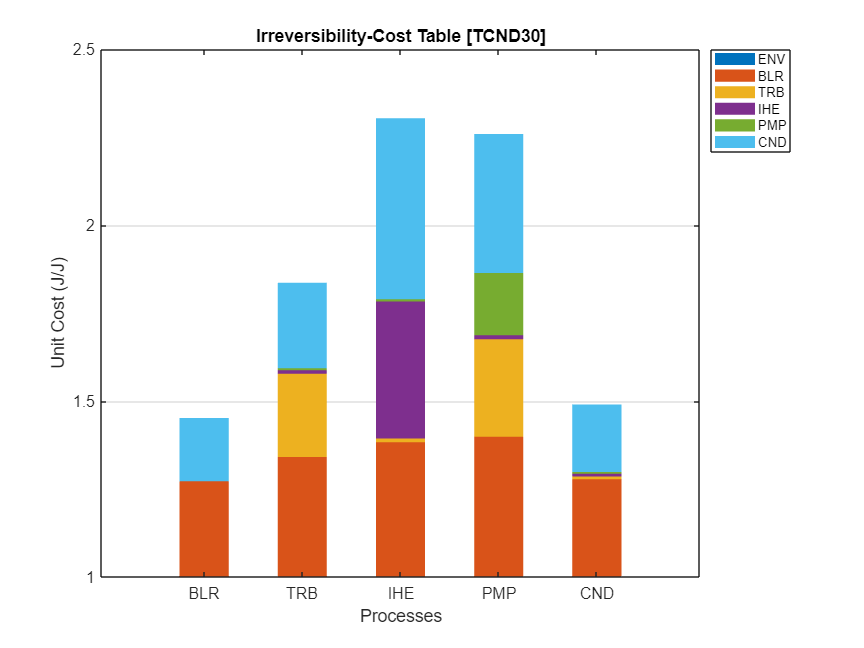

model.graphCost;

**(3) Build model FPR for state TCND45 **

Define the TCND45 conditions for recycling and show the Waste Allocation piechart and the ICT graph

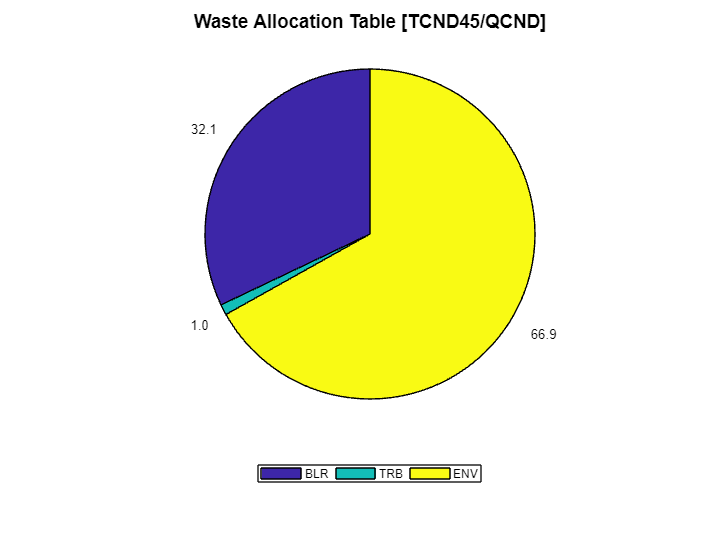

model.State='TCND45';
model.setWasteRecycled('QCND',0.66);
model.graphWasteAllocation;

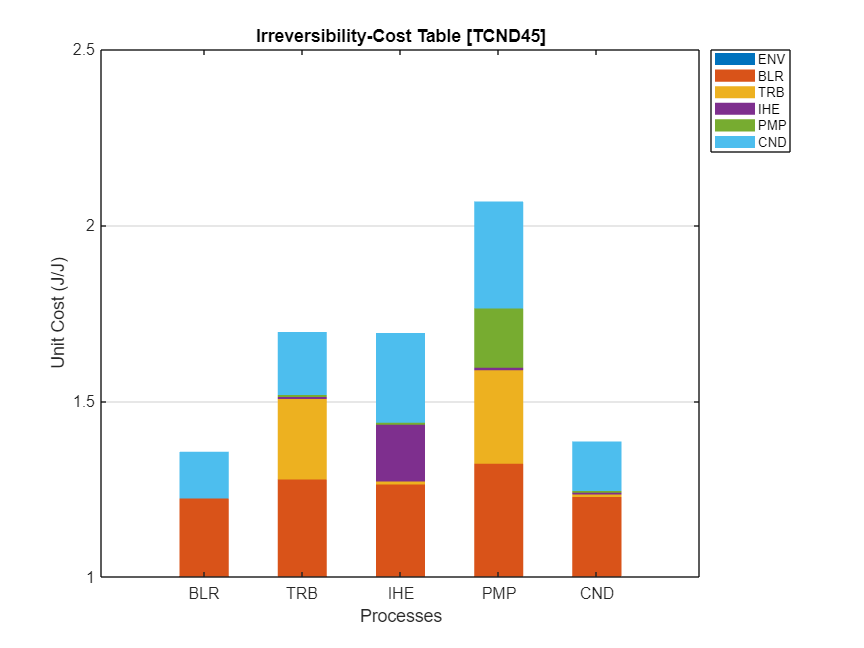

model.graphCost;

**(4) Plot the recycling analysis graph**

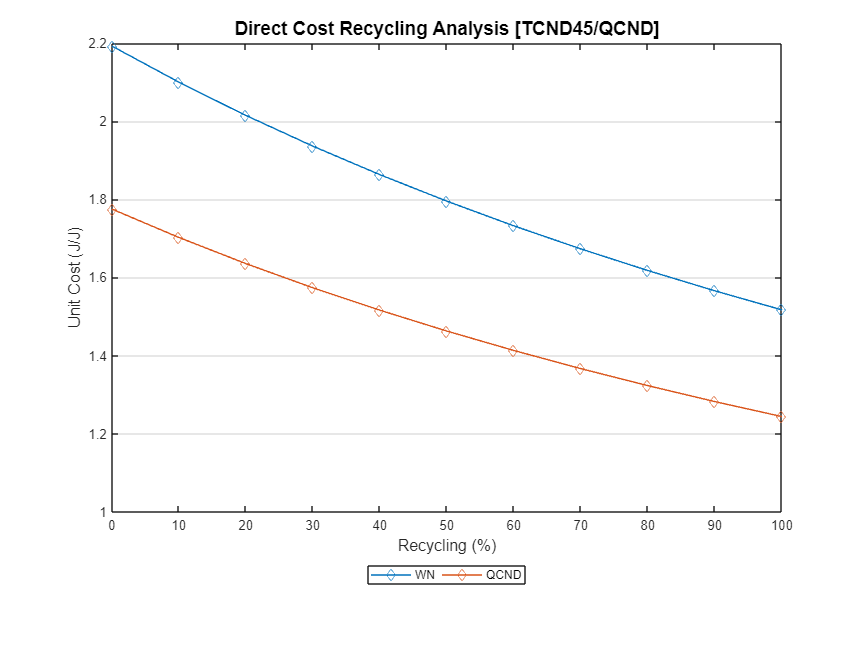

res=model.recyclingAnalysis;
res.graphRecycling(cType.Tables.WASTE_RECYCLING_DIRECT);

**(5) Compare both configurations**

Compare both states using the thermoeconomicDiagnosis function

model.DiagnosisMethod='WASTE_INTERNAL';
model.fuelImpact;

Fuel Impact:   17.8100 (kW)


printResults(model.thermoeconomicDiagnosis);

Diagnosis Summary

 Key      MF(kW)     DI(kW)    DPs(kW)    MF*(kW)    MR*(kW)   DPs*(kW)
------------------------------------------------------------------------
 BLR     -3.5252     0.3700     0.0000    -3.5252    -2.4752     0.0000
 TRB     -0.4136    -0.2870     0.0000    -0.3848     0.0660     0.0000
 IHE     -0.3275    -0.1270     0.0000    -0.4033    -0.2491     0.0000
 PMP     -0.0155     0.0670     0.0000    -0.0236    -0.0187     0.0000
 CND      0.0000     0.0000    17.7870     0.0189     0.0109    24.7942
 ENV     -4.2819     0.0230    17.7870    -4.3180    -2.6662    24.7942


Malfunction Table (kW)

              BLR       TRB       IHE       PMP       CND       DPs
--------------------------------------------------------------------
 BLR       0.0000   -1.0035   -0.3286    0.0000   -0.0890    0.0000
 TRB       0.0000    0.0000    0.0000   -0.0155    0.0000    0.0000
 IHE       0.0000    0.6062    0.0100    0.0000    0.0898    0.0000
 PMP       0.0000   -0.0163   -0.0090

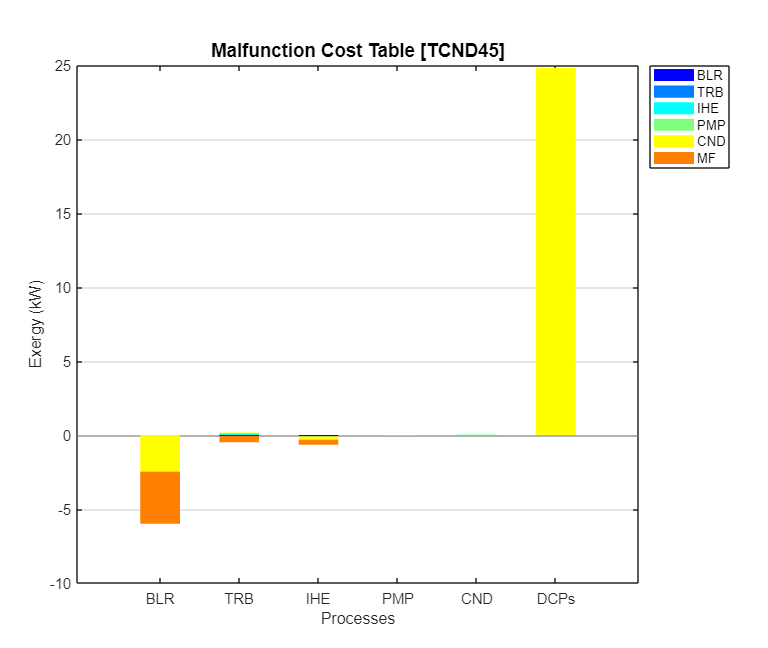

model.graphDiagnosis;

**(6) Show Summary Results**

Show unit cost summary tables and graph

model.printSummary(cType.SummaryTables.FLOW_DIRECT_UNIT_COST);

Flows Direct Unit Exergy Cost (J/J)

 Key      TCND30    TCND45    ETAT75    PBLR15     NoIHE  N_Butane
-------------------------------------------------------------------
 B1       1.4902    1.3849    1.4904    1.5185    1.5957    1.4970
 B2       1.4902    1.3849    1.4904    1.5185    1.5957    1.4970
 B3       1.4902    1.3849    1.4904    1.5185    1.5957    1.4970
 B4       1.4902    1.3849    1.4904    1.5185    1.5957    1.4970
 B5       1.6953    1.5290    1.7312    1.6844    1.8155    1.5695
 B6       1.7937    1.5596    1.8430    1.7802    1.8155    1.6074
 QBLR     1.0000    1.0000    1.0000    1.0000    1.0000    1.0000
 WP       1.8358    1.6961    1.9504    1.8722    1.9658    1.8450
 WN       1.8358    1.6961    1.9504    1.8722    1.9658    1.8450
 QCND     1.4902    1.3849    1.4904    1.5185    1.5957    1.4970



model.printSummary(cType.SummaryTables.FLOW_GENERALIZED_UNIT_COST);

Flows Generalized Unit Cost (c/kWh)

 Key      TCND30    TCND45    ETAT75    PBLR15     NoIHE  N_Butane
-------------------------------------------------------------------
 B1       0.3041    0.2933    0.3089    0.2851    0.2967    0.3402
 B2       0.3041    0.2933    0.3089    0.2851    0.2967    0.3402
 B3       0.3041    0.2933    0.3089    0.2851    0.2967    0.3402
 B4       0.3041    0.2933    0.3089    0.2851    0.2967    0.3402
 B5       1.4707    1.2090    1.4835    1.1977    1.4624    0.7468
 B6       1.4696    1.2282    1.4838    1.2328    1.4624    0.7889
 QBLR     0.0000    0.0000    0.0000    0.0000    0.0000    0.0000
 WP       3.2419    3.2267    3.2722    3.2185    3.2328    3.2871
 WN       3.2419    3.2267    3.2722    3.2185    3.2328    3.2871
 QCND     0.7003    0.6895    0.7050    0.6813    0.6929    0.7364



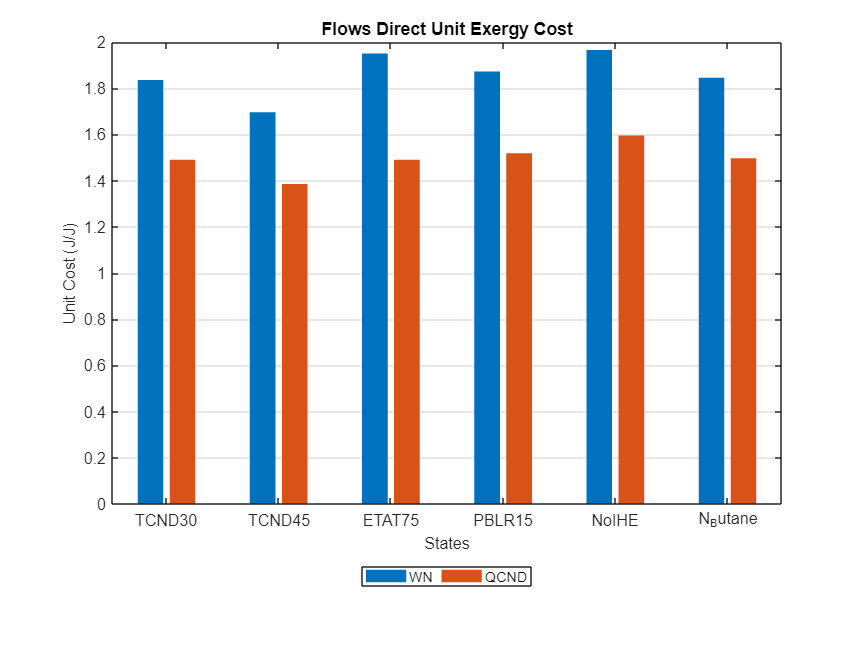

model.graphSummary;